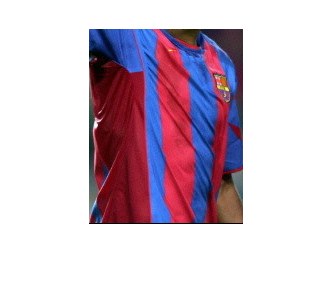

clear all
image=imread('base.jpg');
image=double(image);
figure,imshow(uint8(image))


Image_red = image(:,:,1);
Image_green = image(:,:,2);
Image_blue = image(:,:,3);

[row,col] = size(image(:,:,1));

numBlocksVertical = 4 

numBlocksVertical = 4

numBlocksHoritzonal = 2 

numBlocksHoritzonal = 2

rowSize = uint32(row/numBlocksVertical)

rowSize = uint32
49

colSize = uint32(col/numBlocksHoritzonal)

colSize = uint32
77

pixelsBlock = rowSize * colSize

pixelsBlock = uint32
3773


endrow = uint32(row*8)

endrow = uint32
1560

endcol = uint32(col*5)

endcol = uint32
770

redPixels = 590

bluePixels = 362

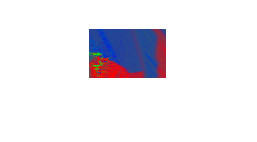

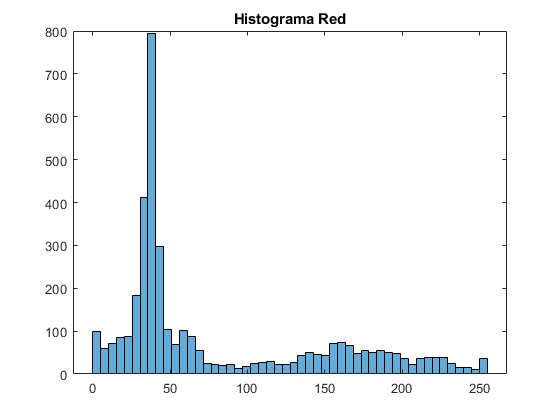

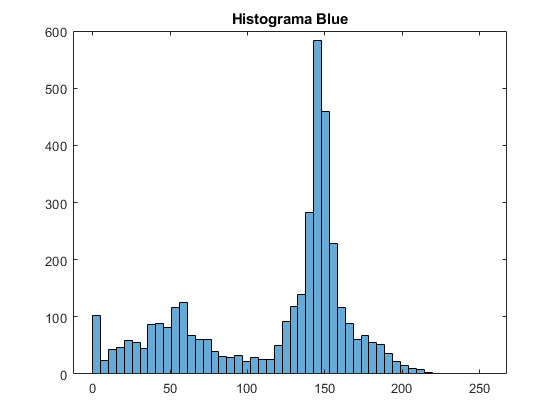

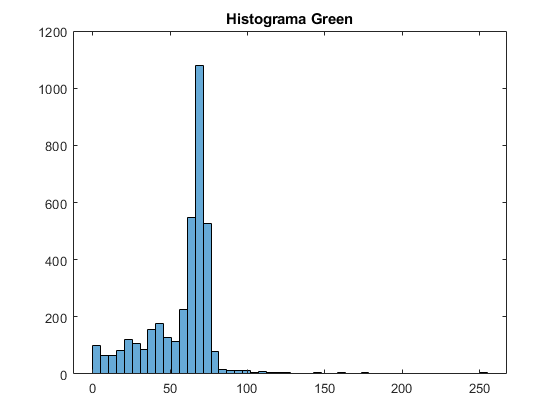

redPixels = 1719

bluePixels = 360

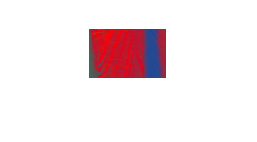

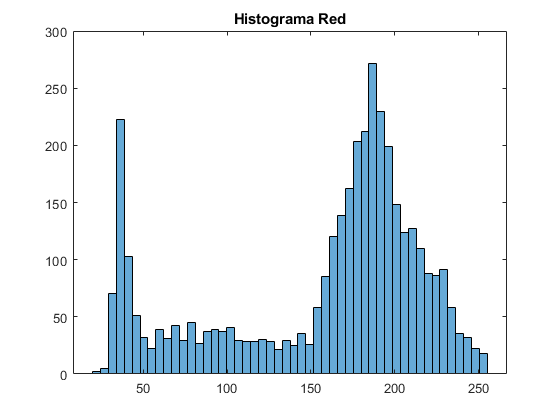

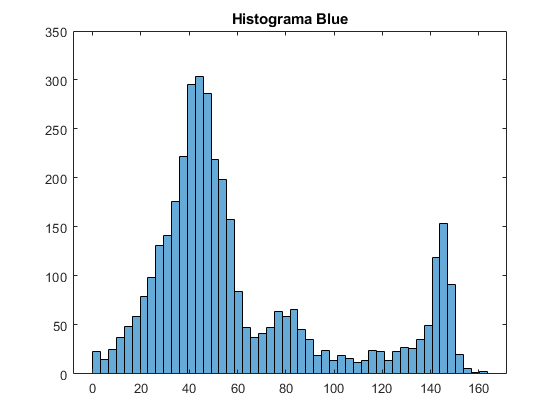

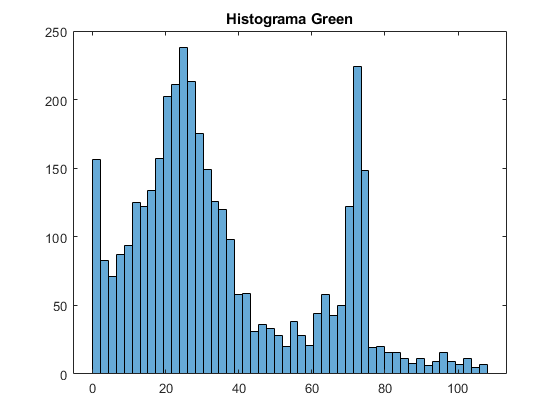


redPixels = 0;
bluePixels = 0;
greenPixels = 0;
isBarsa = 0;

for i = 1:numBlocksHoritzonal
    for j = 1:numBlocksVertical
        startrow = j*rowSize - rowSize -1;
        startcol = i*colSize - colSize -1;
        if (i == 1)
            startcol = i*colSize - colSize + 1;
        end
        if (j == 1)
            startrow = j*rowSize - rowSize + 1;

        end
        endrow = startrow + rowSize -1;
        endcol = startcol + colSize -1;
        redPixels = 0;
        bluePixels = 0;
        greenPixels = 0;
        for y = startrow:endrow 
            for x = startcol:endcol 
              Red = Image_red(y,x);
              Green = Image_green(y,x);
              Blue = Image_blue(y,x);
              
              if (Red >= 75 && Red <= 125)
                  redPixels = redPixels + 1;
              end
              
              if (Blue >= 60 && Blue <= 90)
                  bluePixels = bluePixels + 1;
              end
              
              if (Green >= 110)
                  greenPixels = greenPixels + 1;
              end
            
              NormalizedRed = Red/(Red + Green + Blue);
              NormalizedGreen = Green/(Red + Green + Blue);
              NormalizedBlue = Blue/(Red + Green + Blue);
            
              Image_red(y,x) = NormalizedRed;
              Image_green(y,x) = NormalizedGreen;
              Image_blue(y,x) = NormalizedBlue;
            end
        end
        redPixels
        bluePixels
        if (redPixels >= 0.15*pixelsBlock)
            if (bluePixels >= 0.15*pixelsBlock)
                if (greenPixels <= 0.05*pixelsBlock)
                isBarsa = 1
                end
            end
        end
% %         Descomentar per veure com genera els blocks
        image(:,:,1) = Image_red;
        image(:,:,2) = Image_green;
        image(:,:,3) = Image_blue;
        figure; imshow(uint8(255*image(startrow:endrow,startcol:endcol,:)));
        figure; histogram(Image_red(startrow:endrow,startcol:endcol)*255, 50), title('Histograma Red')
        figure; histogram(Image_blue(startrow:endrow,startcol:endcol)*255,50), title('Histograma Blue')
        figure; histogram(Image_green(startrow:endrow,startcol:endcol)*255,50), title('Histograma Green')
     end
end


image(:,:,1) = Image_red;
image(:,:,2) = Image_green;
image(:,:,3) = Image_blue;

redPixels
bluePixels

figure; imshow(uint8(255*image));

% histogram(image, nBins)
histogram(Image_red(:,:)*255, 50), title('Histograma Red')
histogram(Image_blue(:,:)*255, 50), title('Histograma Blue')
histogram(Image_green(:,:)*255, 50), title('Histograma Green')